# Exergy Cost Calculator Demo

Use ExergyCostCalculator function to compute direct and generalized exergy cost

#### Select the model file

Use uigetfile control to select the model file

file='rorc_model.xlsx';
data=ReadDataModel(file);

#### Select the parameters

States=convertCharsToStrings(data.States);
State=convertStringsToChars(States(1));
Samples=convertCharsToStrings(data.ResourceSamples);
ResourceSample=convertStringsToChars(Samples(1));

#### Compute the Exergy Cost

res=ExergyCostCalculator(data,'State',State,...
    'CostTables','ALL',...
    'ResourceSample',ResourceSample);
printResults(res);

Waste Allocation Table  (%)

 Key       QCND
----------------
 BLR      93.15
 TRB       2.57
 IHE       2.64
 PMP       1.64


Flows Exergy Cost

 Key        B(kW)     B*(kW)    Be*(kW)    Br*(kW)    k*(J/J)   ke*(J/J)   kr*(J/J)
------------------------------------------------------------------------------------
 B1        81.250    121.077    105.477     15.600     1.4902     1.2982     0.1920
 B2        16.960     25.273     22.017      3.256     1.4902     1.2982     0.1920
 B3        14.930     22.248     19.382      2.867     1.4902     1.2982     0.1920
 B4         5.591      8.332      7.258      1.073     1.4902     1.2982     0.1920
 B5         7.627     12.930     11.052      1.879     1.6953     1.4490     0.2463
 B6         9.100     16.323     13.687      2.636     1.7937     1.5041     0.2897
 QBLR      91.790     91.790     91.790      0.000     1.0000     1.0000     0.0000
 WP         2.381      4.371      3.794      0.577     1.8358     1.5933     0.2425
 WN        5

#### Show Irreversibility Cost Graph

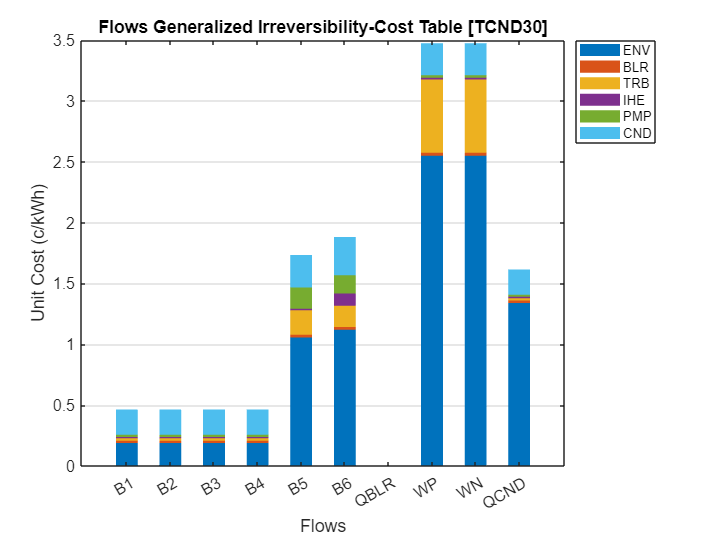

graphCost(res,cType.Tables.FLOW_GENERALIZED_ICT);